function FinLoadCalcs (finShape, tipChord, rootChord, span, sweepAngle, trailingEdgeSweep, velocities, altitudes, AoA)
    
    

# Calculation and Plotting of the Fin Loads over Flight Profiles

    surfaceArea = calculateFinArea(rootChord, tipChord, span);

    % Pre-allocate arrays
    subsonic_loads_array = zeros(length(altitudes), 2); % Columns: [Lift, Drag]
    supersonic_loads_array = zeros(length(altitudes), 2); % Columns: [Lift, Drag]
    transsonic_loads_array = zeros(length(altitudes), 2); % Columns: [Lift, Drag]
    Reynolds_numbers = zeros(size(altitudes));
    Ma_numbers = zeros(size(altitudes)); % Free flow Mach numbers
    effective_mach_numbers = zeros(size(velocities)); % Effective Mach numbers relative to sweep of leading edge

    % Loop through flight profile to calculate loads at each point
    for i = 1:length(altitudes)

        % Mean Aerodynamic Chord to estimate aerodymanic center
        L_MAC = 2/3 * (rootChord+tipChord)/rootChord * (rootChord-tipChord) + tipChord;
        
        % Calculate Reynolds number
        Reynolds_numbers(i) = calculateReynoldsNumber(velocities(i), altitudes(i), L_MAC);

        % Calculate speed of sound and Mach number
        Ma_numbers(i) = calculateMachNumber(velocities(i), altitudes(i)); % Free stream Mach number

        % Adjust Mach number for sweep angle if applicable
        effective_mach_numbers(i) = Ma_numbers(i) * cosd(sweepAngle);
    
        %% Classify Mach regime and calculate loads
        % Subsonic loads (up to and including Mach 1)
        if effective_mach_numbers(i) <= 1
            %subsonic_loads_array(i) = subsonic_loads();
        end
    
        % Supersonic loads (starting at Mach 1.05 not 1.0 because of asymptote at 1)
        if effective_mach_numbers(i) >= 1.05
            [supersonic_loads_array(i, 1), supersonic_loads_array(i, 2)] = supersonic_loads(sweepAngle, AoA, Reynolds_numbers(i), Ma_numbers(i), surfaceArea, velocities(i), altitudes(i));
        end
    
        % Transonic loads (overlapping from Mach 0.8 to 1.2)
        if effective_mach_numbers(i) >= 0.8 && effective_mach_numbers(i) <= 1.2
            %transsonic_loads_array(i) = transsonic_loads();
        end
    end
    
    % Plotting the Loads
    figure;
    plot(altitudes, supersonic_loads_array(:, 1), 'LineWidth', 1.5); % Lift
    hold on;
    plot(altitudes, supersonic_loads_array(:, 2), 'LineWidth', 1.5); % Drag
    grid on;
    xlabel('Altitude (m)');
    ylabel('Aerodynamic Load (N)');
    title('Aerodynamic Loads on Rocket Fin over Altitude');
    legend('Lift Force [N]', 'Drag Force [N]');


# Plotting of the Fin with max Mach Cones

    centerOfPressure = calculateCenterOfPressure(finShape, rootChord, tipChord, span, sweepAngle);
    maxMachNumber = max(Ma_numbers);

    plotFinShapeSupersonic(finShape, tipChord, rootChord, span, sweepAngle, trailingEdgeSweep, surfaceArea, centerOfPressure, maxMachNumber)

end

# Differentiation Between Leading and Trailing Edge

# 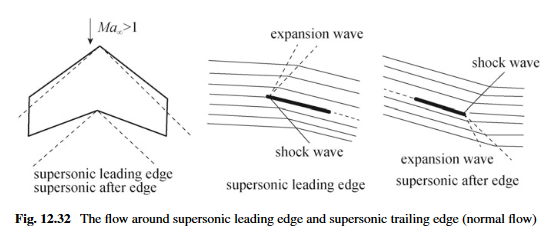

[P. Liu, Aerodynamics, https://doi.org/10.1007/978-981-19-4586-1_12 P. 752f]

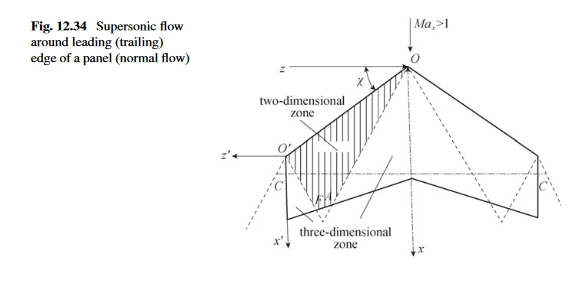

[P. Liu, Aerodynamics, https://doi.org/10.1007/978-981-19-4586-1_12 P. 754]

# Role of Sweep Angle in Supersonic Flow

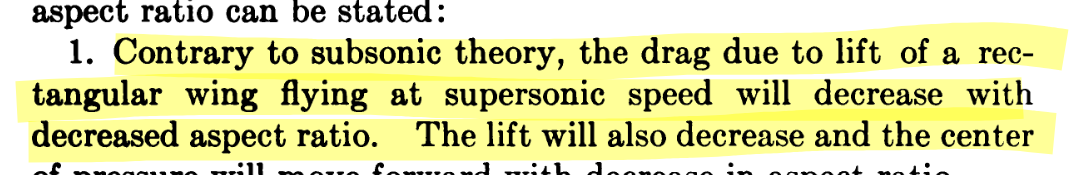

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 148]

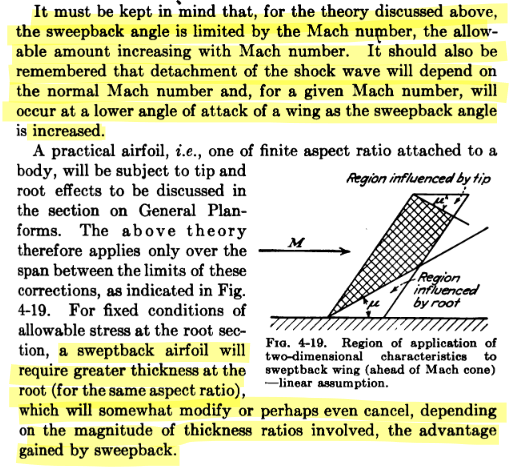

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 135]

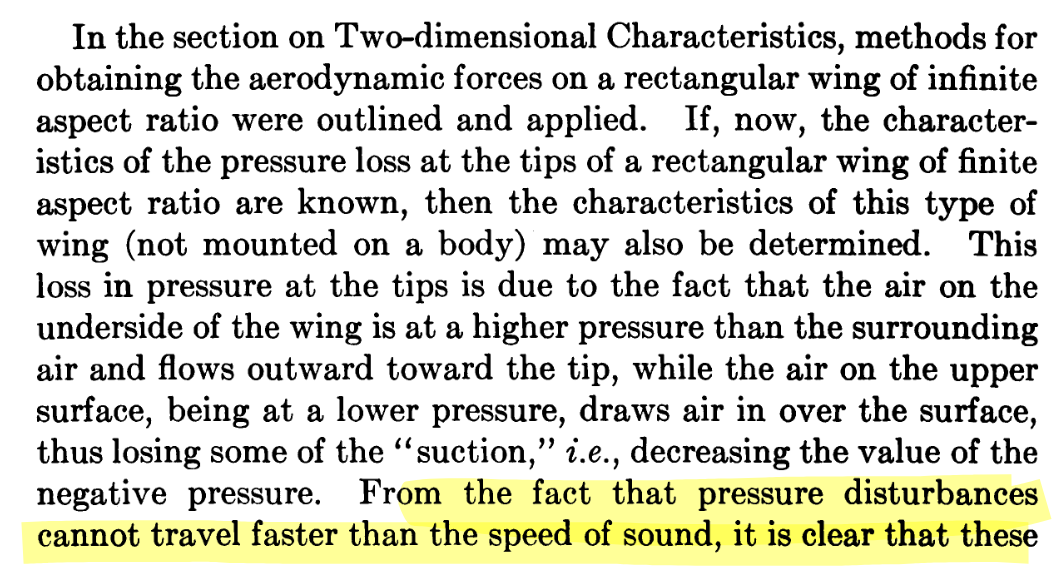

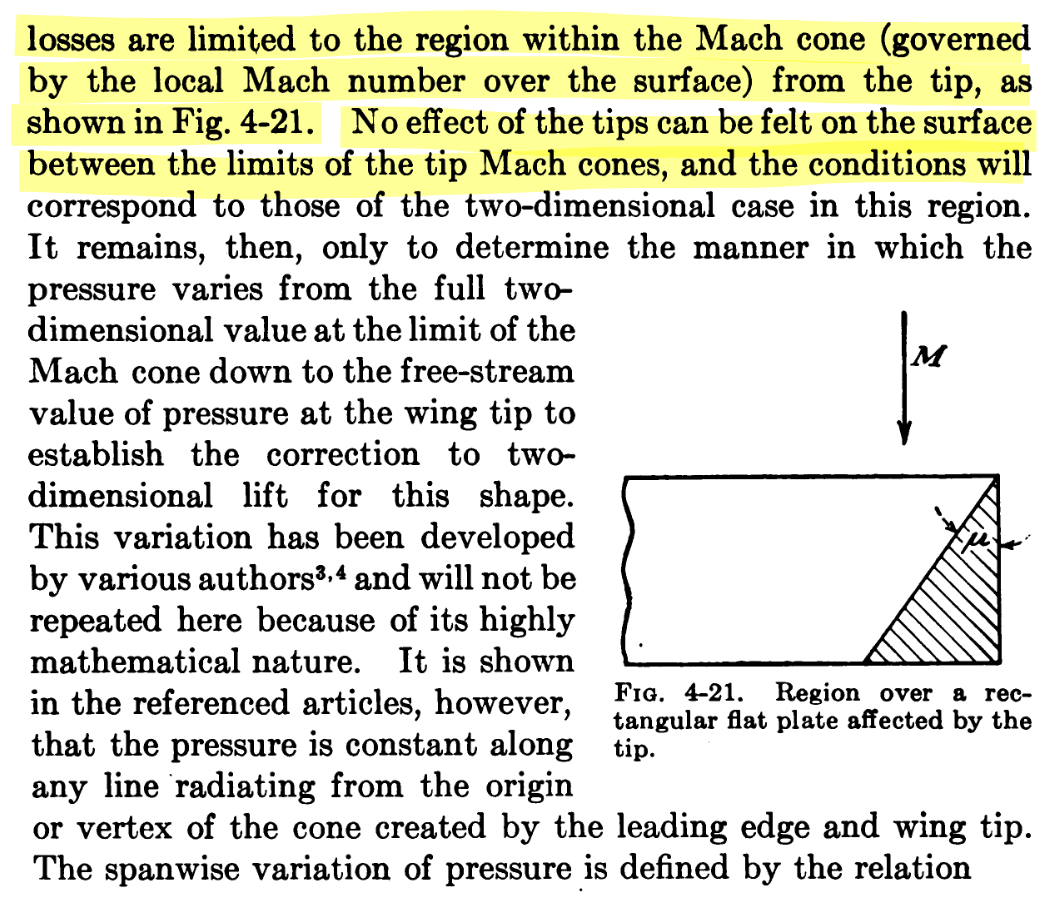

[E. Arthur Bonney - Engineering Supersonic Aerodynamics P. 137]